# Cameras

We render the chess set scene through a camera with a lens . The output is the spectral irradiance at the sensor surface (the optical image).

This script  illustrates how to set the focal distance, and it reveals the depth of field for this double Gauss lens.

## Set up ISETCam

Also, make sure we have docker running.

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the PBRT scene

thisR = piRecipeDefault('scene name','ChessSet');

Read 9 materials.
Read 3 textures.
***Scene parsed.


thisR.set('spatial resolution',512);

## Create a camera with a double Gauss lens

lensname    = 'dgauss.22deg.12.5mm.json';
doubleGauss = piCameraCreate('omni','lens file',lensname);

thisR.set('camera',doubleGauss);

The distance that will be in focus

thisR.set('focus distance',0.8);

Set the camera position a little higher than default.  That makes it easier to see the ruler on the chess board.

thisR.set('from',[0,0.18,-0.5]);

Rotate the camera down a bit.  The (x,y) axes for this scene surpise me.

piCameraRotate(thisR, 'x rot',-10);

Summarize the recipe information.  There is a lot for this scene.  But you can handle it.

thisR.summarize;


File information
-----------
Input:  C:\iset\iset3d-v4\data\V4\ChessSet\ChessSet.pbrt
Output: C:\iset\iset3d-v4\local\ChessSet\ChessSet.pbrt

Renderer information
-----------
Rays per pixel 32
Bounces 5

Camera parameters
-----------
Sub type: omni
Lens file name:   C:\iset\iset3d-v4\data\lens\dgauss.22deg.12.5mm.json
Aperture diameter (mm): 5.00
Focal distance (m):	0.80
Exposure time (s):	1.000000
Field of view (deg):	28.449267

Film parameters
-----------
subtype: gbuffer
x,y resolution: 512 512 (samples)
diagonal:   10 (mm)

Lookat parameters
-----------
from:	0.000 0.180 -0.500
to:	0.000 -0.102 0.466
up:	0.000 1.000 0.000
object distance: 1.006 (m)
                                                  material             positions (m)           sizes (m)     
                                            ____________________    ___________________    __________________

    000

## Write and render

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   1.38
Render: docker --context remote-mux exec -i  pbrt-gpu-Windows18243 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.12
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.74
Complete render took: 1.13e+01 seconds.*** Rendering time for ChessSet:  11.3 sec ***

exr2bin done.

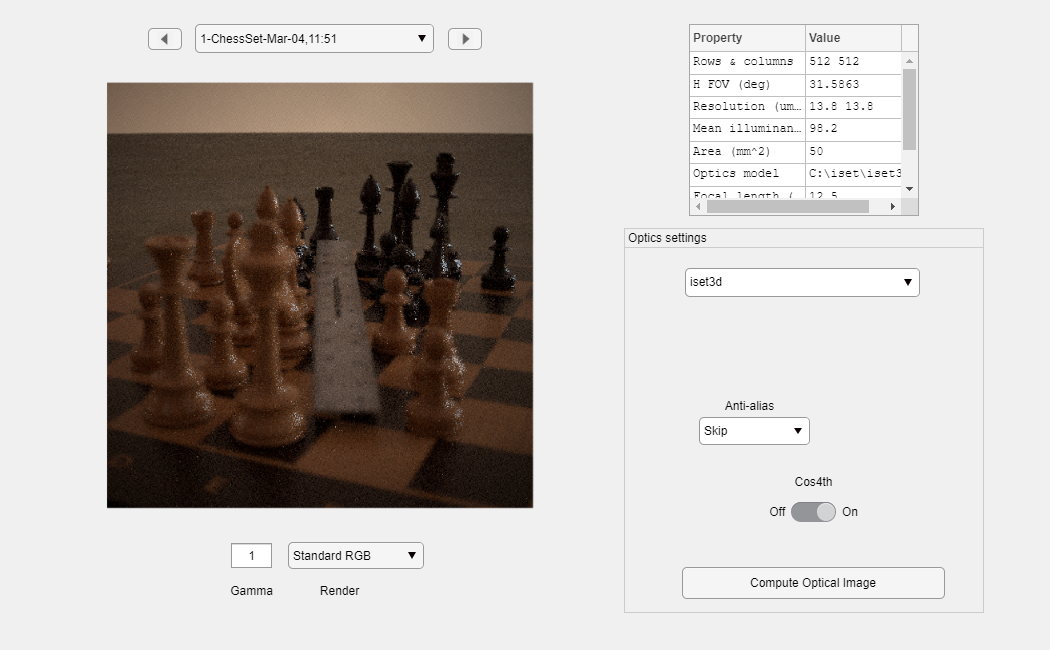

piWRS(thisR,'render type','radiance'); 

## Change the focus distance to 0.4m

 Rsync Put: wsl rsync -r -t /mnt/c/iset/iset3d-v4/local/ChessSet/ david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/
Pushed scene to remote in:   0.95
Render: docker --context remote-mux exec -i  pbrt-gpu-Windows18243 sh -c "cd /iset/iset3d-v4/local/ChessSet && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/ChessSet.exr ChessSet.pbrt"
Successfuly rendered remotely in:   7.18
 Rsync Pull: wsl rsync -r david@muxreconrt.stanford.edu:/home/david/iset/iset3d-v4/local/ChessSet/renderings/ /mnt/c/iset/iset3d-v4/local/ChessSet/renderings
Retrieved output in:   1.73
Complete render took: 1.09e+01 seconds.*** Rendering time for ChessSet:  10.9 sec ***

exr2bin done.

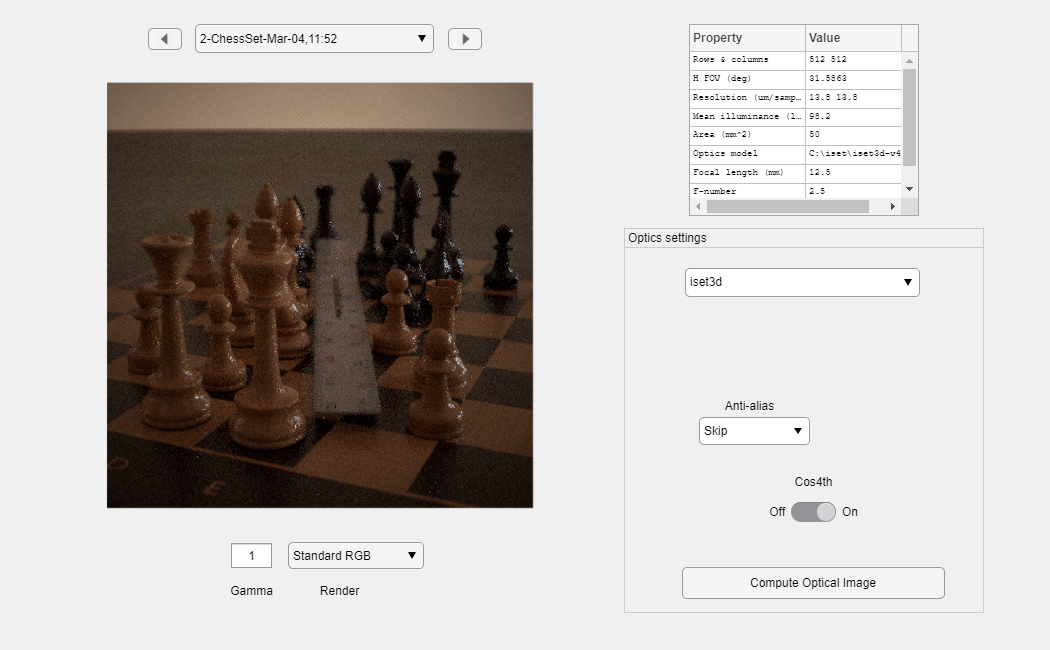

thisR.set('focus distance',0.4);
piWRS(thisR,'render type','radiance'); 